# 주파수영역 제어기 설계 입문 (한글판)

원문 : Control Tutorials for MATLAB and Simulink — Introduction: Frequency Domain Methods 한글 정리 : 제어시스템설계 · 충남대학교 자율운항시스템공학과

**이 문서는 9~10 주차 예습용입니다.** 지금 다 이해하지 못해도 괜찮습니다.

이 문서에서 하는 것

- 이득여유와 위상여유가 무엇인지 이해한다

- 나이퀴스트 선도를 읽는다

- 보드 선도에서 폐루프 성능을 짐작한다

오늘 쓰는 MATLAB 명령 — `bode`, `margin`, `nyquist`, `feedback`, `step`

clc; close all;
s = tf('s');

## 1. 왜 주파수영역인가

선형 시불변 시스템에는 아주 중요한 성질이 있습니다.

**정현파를 넣으면 같은 주파수의 정현파가 나온다.** 다만 크기와 위상이 달라진다.

그 크기비와 위상차를 주파수별로 모아 놓은 것이 **주파수응답**입니다. 보드 선도는 그것을 그림으로 그린 것일 뿐입니다.

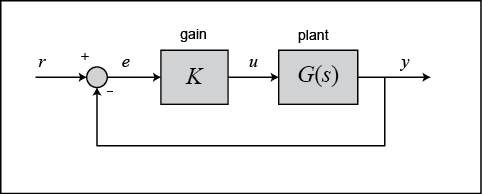

정현파를 넣으면 크기와 위상만 달라진 정현파가 나온다

시간영역과 무엇이 다른가

- 시간영역 — "얼마나 빠른가, 얼마나 흔들리는가" 를 직접 본다

- 주파수영역 — "**얼마나 여유가 있는가**" 를 본다

실무에서 주파수영역을 좋아하는 이유는 이렇습니다.

- 모델이 정확하지 않아도 **실험으로 직접 잴 수 있다** (사인파를 넣어 보면 된다)

- **얼마나 더 나빠져도 버티는가**를 숫자로 준다 (이것이 여유다)

## 2. 이득여유와 위상여유

폐루프가 불안정해지는 조건은 이것입니다.


$$1 + L(j\omega) = 0 \qquad \Rightarrow \qquad L(j\omega) = -1$$


즉 개루프 주파수응답이 **크기 **$1$**, 위상 **$-180^\circ$ 인 점에 닿으면 위험합니다. 그 점에서 얼마나 떨어져 있는가가 **여유**입니다.

- **이득여유 (GM)** — 위상이 $-180^\circ$ 인 주파수에서, 크기를 몇 배 더 키우면 $1$ 이 되는가

- **위상여유 (PM)** — 크기가 $1$ 인 주파수에서, 위상이 $-180^\circ$ 까지 몇 도 남았는가

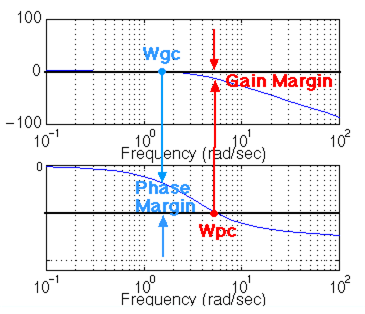

보드 선도에서 이득여유와 위상여유를 읽는 자리

실무 기준

- 이득여유 $6\,\mathrm{dB}$ 이상 (약 2 배)

- 위상여유 $30^\circ \sim 60^\circ$

L1 = 1/(s*(s+1)^2);

figure;
margin(L1); grid on;
[Gm, Pm, Wcg, Wcp] = margin(L1);

fprintf('=== 이득여유와 위상여유 ===\n');
fprintf('  L(s) = 1/(s(s+1)^2)\n');
fprintf('  이득여유 GM = %.2f 배 (%.1f dB)  at %.3f rad/s\n', Gm, 20*log10(Gm), Wcg);
fprintf('  위상여유 PM = %.1f 도             at %.3f rad/s\n\n', Pm, Wcp);

## 2-1. 여유가 줄면 어떻게 되는가

이득을 키우면 크기 곡선이 위로 올라가므로 여유가 줄어듭니다. $K$ 를 이득여유만큼 키우면 여유가 정확히 $0$ 이 되어 **지속진동**이 나옵니다.

t = (0:0.05:60)';
figure;
hold on; grid on;
for K = [0.5 1 Gm 1.5*Gm]
    T = feedback(K*L1, 1);
    if max(real(pole(T))) < 0.05
        plot(t, step(T, t), 'LineWidth', 2, 'DisplayName', sprintf('K = %.2f', K));
    end
end
yline(1, 'k--', 'HandleVisibility','off');
xlabel('시간 [s]'); ylabel('출력'); ylim([-0.5 2.5]);
legend('Location','northeast');
title(sprintf('K = %.2f (= 이득여유) 에서 지속진동이 된다', Gm));

fprintf('=== 이득을 키우면 ===\n');
fprintf('     K     위상여유[도]   가장 오른쪽 극점 실수부\n');
fprintf('  ------  -------------  ---------------------\n');
for K = [0.5 1 Gm 1.5*Gm]
    [~, pm] = margin(K*L1);
    fprintf('  %6.2f  %13.1f  %21.4f\n', K, pm, max(real(pole(feedback(K*L1,1)))));
end
fprintf('\n');

## 3. 나이퀴스트 선도

보드 선도가 크기와 위상을 **따로** 그린 것이라면, 나이퀴스트 선도는 둘을 **한 평면에** 그린 것입니다.

$\omega$ 를 $-\infty$ 에서 $+\infty$ 까지 훑으며 복소수 $L(j\omega)$ 를 찍습니다. 그러면 여유가 $-1$** 점까지의 거리**로 눈에 보입니다.

figure;
nyquist(0.5*L1); grid on;
title('나이퀴스트 선도 : -1 점(빨간 +)에 얼마나 가까운가');

## 3-1. 코시 편각원리와 나이퀴스트 판정

나이퀴스트 판정의 바탕은 복소해석의 **편각원리**입니다. 말로 풀면 이렇습니다.

- $s$ 평면에서 어떤 닫힌 곡선을 따라 한 바퀴 돌면

- $L(s)$ 도 어떤 곡선을 그리며 원점을 몇 바퀴 돈다

- 그 **회전 수**가 곡선 안에 든 극점과 영점의 개수 차이와 같다

이것을 $1 + L(s)$ 에 적용하면 **나이퀴스트 판정**이 나옵니다.


$$Z = N + P$$


- $Z$ — 우반면에 있는 **폐루프** 극점의 개수 (이것이 $0$ 이라야 안정)

- $N$ — 나이퀴스트 선도가 $-1$ 점을 **시계 방향으로** 감은 횟수

- $P$ — 우반면에 있는 **개루프** 극점의 개수

실무에서 쓰는 규칙은 대개 이 한 줄로 줄어듭니다.

**개루프가 안정하면(**$P = 0$**), 나이퀴스트 선도가 **$-1$** 점을 감지 않아야 안정**

fprintf('=== 나이퀴스트 판정 확인 ===\n');
for K = [0.5 2]
    T = feedback(K*L1, 1);
    nz = sum(real(pole(T)) > 0);
    fprintf('  K = %.1f : 우반면 폐루프 극점 %d 개 -> %s\n', ...
            K, nz, string(nz == 0) + " (0 이면 안정)");
end
fprintf('\n');

## 4. 보드 선도에서 폐루프 성능 짐작하기

개루프 보드 선도만 보고 폐루프 성능을 대략 알 수 있습니다. 이것이 주파수영역 설계의 힘입니다.

**위상여유와 감쇠비**


$$\zeta \approx \frac{PM[^\circ]}{100}$$


위상여유 $50^\circ$ 면 감쇠비가 대략 $0.5$ 라는 뜻입니다. 그러면 4주차 공식으로 오버슈트도 짐작됩니다.

**대역폭과 빠르기**

- 대역폭이 넓을수록 응답이 빠르다

- 대략 $\omega_{BW} \approx (1 \sim 2)\,\omega_n$

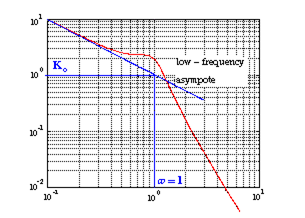

저주파 점근선의 높이가 정상상태 오차를 정한다

fprintf('=== 위상여유와 실제 감쇠비 ===\n');
fprintf('     K     위상여유[도]  PM/100  실제 오버슈트[%%]  공식 예측[%%]\n');
fprintf('  ------  ------------  ------  ----------------  ------------\n');
for K = [0.2 0.4 0.6 0.8]
    [~, pm] = margin(K*L1);
    T = feedback(K*L1, 1);
    ii = stepinfo(T);
    z_est = pm/100;
    if z_est < 1
        os_est = 100*exp(-z_est*pi/sqrt(1-z_est^2));
    else
        os_est = 0;
    end
    fprintf('  %6.2f  %12.1f  %6.3f  %16.1f  %12.1f\n', ...
            K, pm, z_est, ii.Overshoot, os_est);
end
fprintf('  --> 딱 맞지는 않지만 **짐작하기에는 충분합니다.**\n\n');

## 5. 근궤적과 주파수영역 — 같은 것의 두 얼굴

두 방법은 서로 다른 것을 보는 것이 아니라 **같은 것을 다른 각도에서** 봅니다.

| | 근궤적 | 주파수영역 | |---|---|---| | 보는 것 | 극점이 어디 있는가 | $-1$ 점에서 얼마나 떨어져 있는가 | | 필요한 것 | **모델(전달함수)** | 모델 또는 **실험 데이터** | | 잘 보이는 것 | 과도응답 (오버슈트, 정착시간) | 안정 여유, 잡음 억제 | | 잘 안 보이는 것 | 모델 오차에 대한 여유 | 극점 위치 |

**둘 다 할 줄 알아야** 상황에 맞게 골라 쓸 수 있습니다.

- 모델이 정확하다 $\rightarrow$ 근궤적이 편하다

- 모델이 불확실하거나 실험 데이터만 있다 $\rightarrow$ 주파수영역이 낫다

figure('Position',[80 80 950 400]);
tiledlayout(1,2,'TileSpacing','compact');
nexttile
rlocus(L1); grid on; xlim([-3 1]); ylim([-2 2]);
title('근궤적 : 극점이 어디로 가는가');
nexttile
nyquist(0.5*L1); grid on;
title('나이퀴스트 : -1 점에서 얼마나 떨어졌는가');

## 6. 정리

- 불안정의 조건은 $L(j\omega) = -1$. 여유란 **그 점에서 얼마나 떨어졌는가**이다

- **이득여유** 6 dB 이상, **위상여유** $30^\circ \sim 60^\circ$ 가 실무 기준

- 나이퀴스트 판정 : $Z = N + P$. 개루프가 안정하면 $-1$ 을 감지 않아야 한다

- 위상여유로 감쇠비를 짐작할 수 있다 : $\zeta \approx PM/100$

- 근궤적과 주파수영역은 **같은 것의 두 얼굴**이다

이 과목의 9, 10 주차에서 자세히 다룹니다.